# Método de Horner


$$P(x)=x^2$$
 


$$P(x)=0+0x+1x^2$$


clear
a = [0,0,1]

a =      0     0     1


%x = 1
%x = [-1,0,1]
%x = -2:2
x = -2:0.1:2

x =    -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000



yHorner = MHorner(a,x)

yHorner =     4.0000    3.6100    3.2400    2.8900    2.5600    2.2500    1.9600    1.6900    1.4400    1.2100    1.0000    0.8100    0.6400    0.4900    0.3600    0.2500    0.1600    0.0900    0.0400    0.0100         0    0.0100    0.0400    0.0900    0.1600    0.2500    0.3600    0.4900    0.6400    0.8100    1.0000    1.2100    1.4400    1.6900    1.9600    2.2500    2.5600    2.8900    3.2400    3.6100    4.0000



%help polyval
%a = flip(a)
a = a(end: -1:1)

a =      1     0     0



yPolyval = polyval(a,x)

yPolyval =     4.0000    3.6100    3.2400    2.8900    2.5600    2.2500    1.9600    1.6900    1.4400    1.2100    1.0000    0.8100    0.6400    0.4900    0.3600    0.2500    0.1600    0.0900    0.0400    0.0100         0    0.0100    0.0400    0.0900    0.1600    0.2500    0.3600    0.4900    0.6400    0.8100    1.0000    1.2100    1.4400    1.6900    1.9600    2.2500    2.5600    2.8900    3.2400    3.6100    4.0000



erroCometido = abs(yHorner-yPolyval)

erroCometido =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


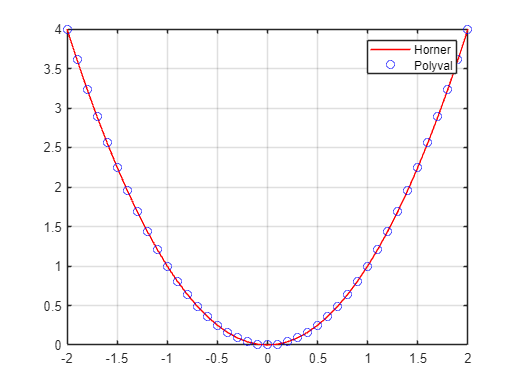



plot(x,yHorner,"-r")
hold on
plot(x,yPolyval,"ob")
legend("Horner","Polyval")
grid on
hold off


A = [x.',yHorner.',yPolyval.',erroCometido.'];
disp(upper("            matriz de resultados"))

            MATRIZ DE RESULTADOS


fprintf("\n      x\t     yHorner   yPolyval\t     erro")


      x	     yHorner   yPolyval	     erro

disp(A)

   -2.0000    4.0000    4.0000         0
   -1.9000    3.6100    3.6100         0
   -1.8000    3.2400    3.2400         0
   -1.7000    2.8900    2.8900         0
   -1.6000    2.5600    2.5600         0
   -1.5000    2.2500    2.2500         0
   -1.4000    1.9600    1.9600         0
   -1.3000    1.6900    1.6900         0
   -1.2000    1.4400    1.4400         0
   -1.1000    1.2100    1.2100         0
   -1.0000    1.0000    1.0000         0
   -0.9000    0.8100    0.8100         0
   -0.8000    0.6400    0.6400         0
   -0.7000    0.4900    0.4900         0
   -0.6000    0.3600    0.3600         0
   -0.5000    0.2500    0.2500         0
   -0.4000    0.1600    0.1600         0
   -0.3000    0.0900    0.0900         0
   -0.2000    0.0400    0.0400         0
   -0.1000    0.0100    0.0100         0
         0         0         0         0
    0.1000    0.0100    0.0100         0
    0.2000    0.0400    0.0400         0
    0.3000    0.0900    0.0900         0
    0.4000    0.




tabelaResultados = array2table(A,"VariableNames", ...
    ["x","yHorner","yPolyval","erro"])

tabelaResultados = 41×4 table
     x      yHorner    yPolyval    erro
    ____    _______    ________    ____

      -2        4           4       0  
    -1.9     3.61        3.61       0  
    -1.8     3.24        3.24       0  
    -1.7     2.89        2.89       0  
    -1.6     2.56        2.56       0  
    -1.5     2.25        2.25       0  
    -1.4     1.96        1.96       0  
    -1.3     1.69        1.69       0  
    -1.2     1.44        1.44       0  
    -1.1     1.21        1.21       0  
      -1        1           1       0  
    -0.9     0.81        0.81       0  
    -0.8     0.64        0.64       0  
    -0.7     0.49        0.49       0  
    -0.6     0.36        0.36       0  
    -0.5     0.25        0.25       0  



writetable(tabelaResultados,"teste.xlsx")
b=readtable("teste.xlsx","Range","A2:D2")

b = 1×4 table
    Var1    Var2    Var3    Var4
    ____    ____    ____    ____

     -2      4       4       0  
